We consider an axially moving beam under 1:3 internal resonance between the first two bending modes. The equation of motion is given by


$$\ddot{\mathbf{u}}+(\mathbf{C}+\mathbf{G})\dot{\mathbf{u}}+\mathbf{f}(\mathbf{u},\dot{\mathbf{u}})=\epsilon\Omega^2\mathbf{g}\cos\Omega t$$


where $\mathbf{G}^\top=-\mathbf{G}$ is a gyroscopic matrix. With viscoelastic material model, the system has nonlinear damping. In addition, the beam is subject to base excitation such that the forcing amplitude is a function of forcing frequency.

In this notebook, we will calculate the forced response curve of the system with/without the nonlinear damping taken into consideration to explore the effects of nonlinear damping

## Nonlinear Damping

### Setup Dynamical System

clear all;
n = 10;
[mass,damp,gyro,stiff,fnl,fext] = build_model(n,'nonlinear_damp');

the first four eigenvalues for undamped system


lamd =    0.0000 + 3.1954i
   0.0000 - 3.1954i
   0.0000 + 9.5862i
   0.0000 - 9.5862i


**Create model**

- Given the assembled damping matrix $\mathbf{C}+\mathbf{G}$ is not Rayleigh damping anymore. One should set the corresponding Options in DS to be false.

- The BaseExcitation option in DS should be set true to account for the $\Omega$-dependent forcing amplitude.

DS = DynamicalSystem();
set(DS,'M',mass,'C',damp+gyro,'K',stiff,'fnl',fnl);
set(DS.Options,'Emax',6,'Nmax',10,'notation','multiindex');
set(DS.Options,'RayleighDamping',false,'BaseExcitation',true);

% Forcing
h = 1.5e-4; % h characterizes the vibration amplitude of base excitation. It plays the role of epsilon here
kappas = [-1; 1];
coeffs = [fext fext]/2;
DS.add_forcing(coeffs, kappas, h);

### Linear Modal analysis

[V,D,W] = DS.linear_spectral_analysis();


 The first 6 eigenvalues are given as 
  -0.0180 + 3.1954i
  -0.0180 - 3.1954i
  -0.2721 + 9.5828i
  -0.2721 - 9.5828i
  -1.3571 +19.6071i
  -1.3571 -19.6071i



**Choose Master subspace**

Due to the 1:3 internal resonance, we take the first two complex conjugate pairs of modes as the spectral subspace to SSM. So we hvae resonant_modes = [1 2 3 4].

S = SSM(DS);
set(S.Options, 'reltol', 1,'notation','multiindex');
resonant_modes = [1 2 3 4];
order = 3;
outdof = [1 2];

### Primary resonance of the first mode

We consider the case that $\Omega\approx\omega_1$. Although the second mode is not excited externally ($f_2=\langle \phi_2,f^\mathrm{ext}\rangle=0$), the response of the second mode is nontrivial due to the modal interactions.

freqrange = [0.98 1.04]*imag(D(1));
set(S.FRCOptions, 'nCycle',500, 'initialSolver', 'fsolve');
set(S.contOptions, 'PtMX', 300, 'h0', 0.1, 'h_max', 0.2, 'h_min', 1e-3);
set(S.FRCOptions, 'coordinates', 'polar');

We first compute the FRC with O(3,5,7) expansion of SSM and then check the convergence of FRC with increasing orders. 

(near) outer resonance detected for the following combination of master eigenvalues
     0     0     2     0
     1     0     2     0
     0     0     3     1
     1     1     2     0
     3     0     1     0
     0     2     3     0
     1     0     3     1
     2     1     2     0
     4     0     1     0
     0     0     4     2
     0     3     3     0
     1     1     3     1
     2     2     2     0
     3     0     2     1
     4     1     1     0
     6     0     0     0
     0     2     4     1
     1     0     4     2
     1     3     3     0
     2     1     3     1
     3     2     2     0
     4     0     2     1
     5     1     1     0
     7     0     0     0
     0     0     5     3
     0     3     4     1
     1     1     4     2
     1     4     3     0
     2     2     3     1
     3     0     3     2
     3     3     2     0
     4     1     2     1
     5     2     1     0
     6     0     1     1
     7     1     0     0
     0     2     5     2
     0     5    

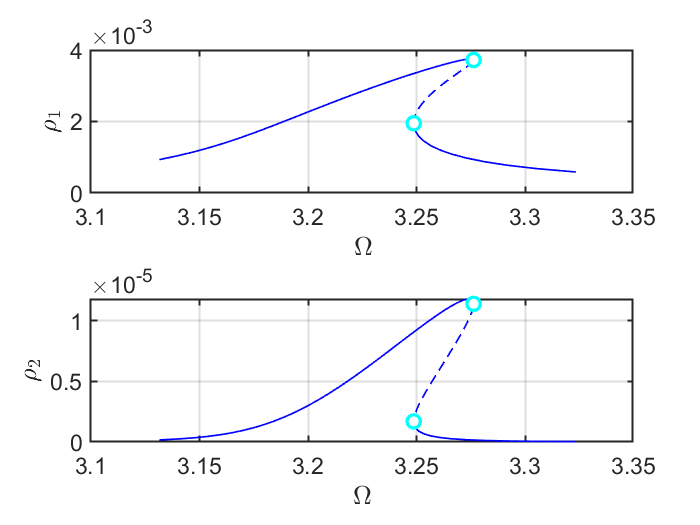

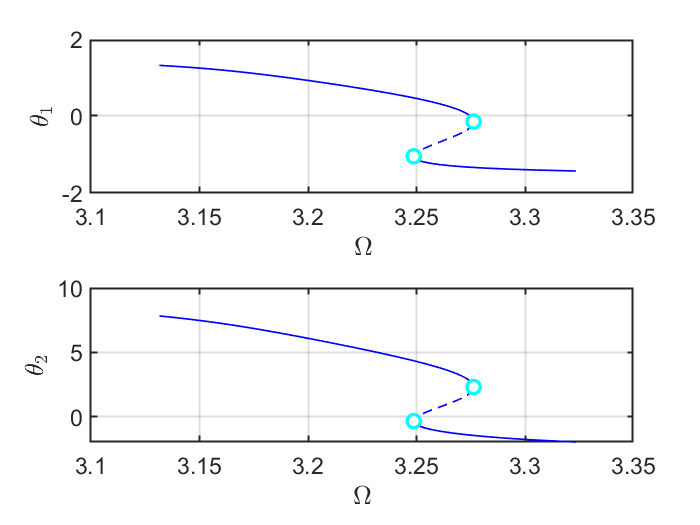

the forcing frequency 3.1315e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1324e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1402e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1473e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1536e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1595e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1650e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1702e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1752e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1800e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequenc

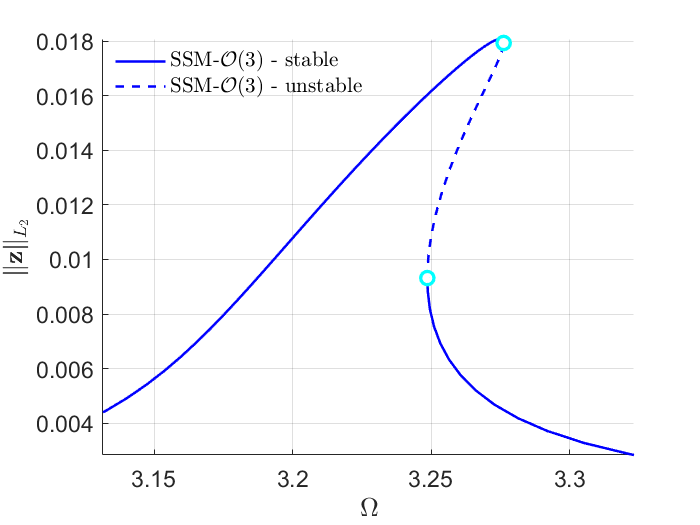

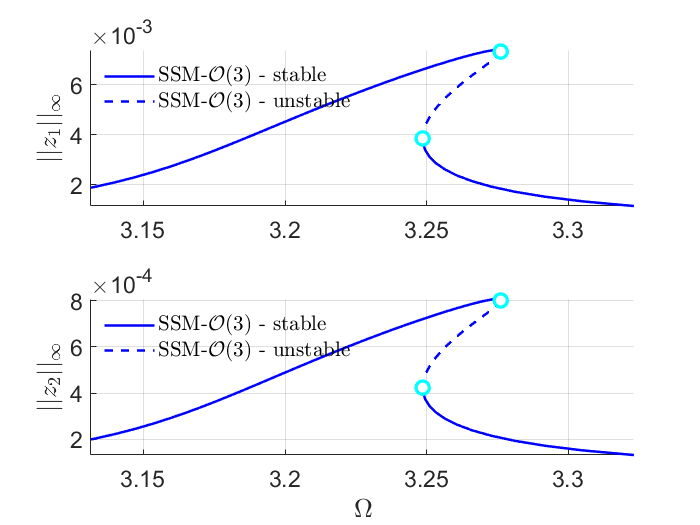

% O(3)
start = tic;
FRC_ND_O3 = S.SSM_isol2ep('isol-nd-3',resonant_modes, order, [1 3], 'freq', freqrange,outdof);

(near) outer resonance detected for the following combination of master eigenvalues
     0     0     2     0
     1     0     2     0
     0     0     3     1
     1     1     2     0
     3     0     1     0
     0     2     3     0
     1     0     3     1
     2     1     2     0
     4     0     1     0
     0     0     4     2
     0     3     3     0
     1     1     3     1
     2     2     2     0
     3     0     2     1
     4     1     1     0
     6     0     0     0
     0     2     4     1
     1     0     4     2
     1     3     3     0
     2     1     3     1
     3     2     2     0
     4     0     2     1
     5     1     1     0
     7     0     0     0
     0     0     5     3
     0     3     4     1
     1     1     4     2
     1     4     3     0
     2     2     3     1
     3     0     3     2
     3     3     2     0
     4     1     2     1
     5     2     1     0
     6     0     1     1
     7     1     0     0
     0     2     5     2
     0     5    

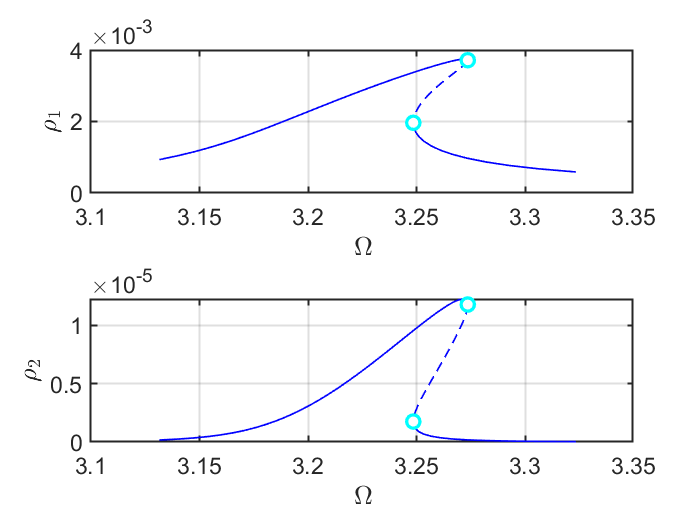

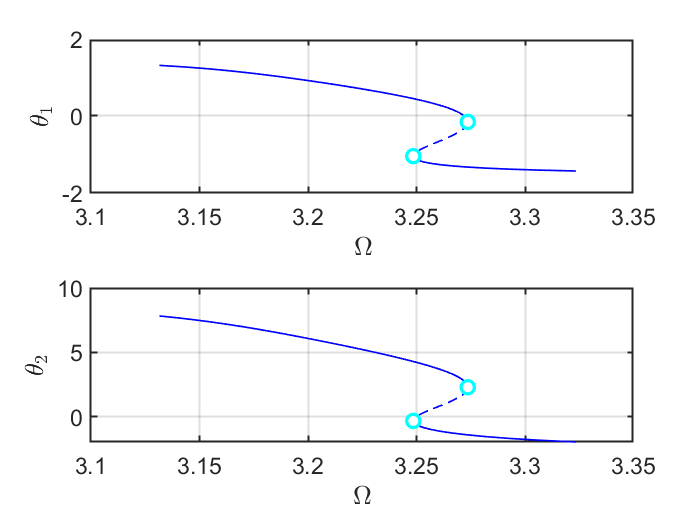

the forcing frequency 3.1315e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1329e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1407e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1476e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1540e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1598e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1653e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1705e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1754e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1801e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequenc

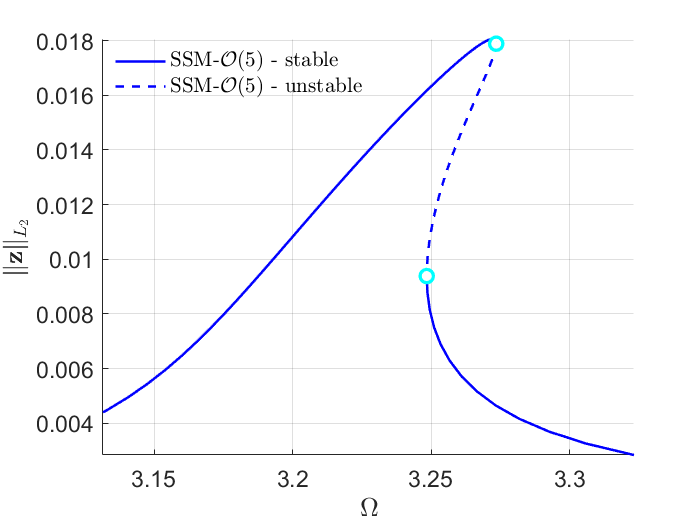

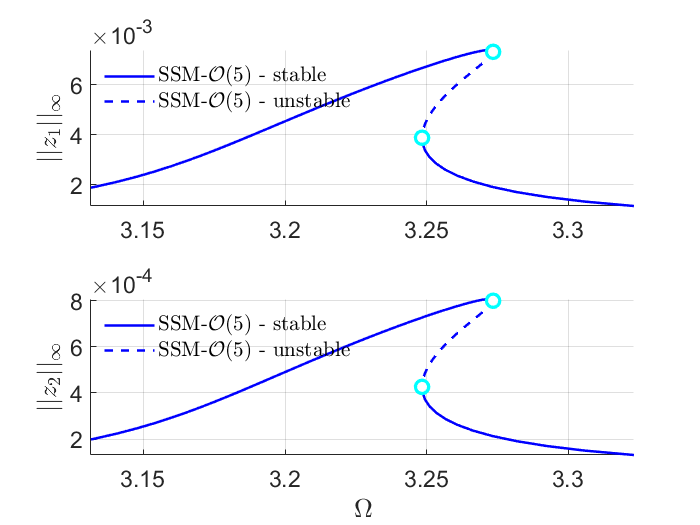

timings.FRC_ND_O3 = toc(start);
% O(5)
sol = ep_read_solution('isol-nd-3.ep',1);
start = tic;
FRC_ND_O5 = S.SSM_isol2ep('isol-nd-5',resonant_modes, order+2, [1 3],...
    'freq', freqrange,outdof,{sol.p,sol.x});

(near) outer resonance detected for the following combination of master eigenvalues
     0     0     2     0
     1     0     2     0
     0     0     3     1
     1     1     2     0
     3     0     1     0
     0     2     3     0
     1     0     3     1
     2     1     2     0
     4     0     1     0
     0     0     4     2
     0     3     3     0
     1     1     3     1
     2     2     2     0
     3     0     2     1
     4     1     1     0
     6     0     0     0
     0     2     4     1
     1     0     4     2
     1     3     3     0
     2     1     3     1
     3     2     2     0
     4     0     2     1
     5     1     1     0
     7     0     0     0
     0     0     5     3
     0     3     4     1
     1     1     4     2
     1     4     3     0
     2     2     3     1
     3     0     3     2
     3     3     2     0
     4     1     2     1
     5     2     1     0
     6     0     1     1
     7     1     0     0
     0     2     5     2
     0     5    

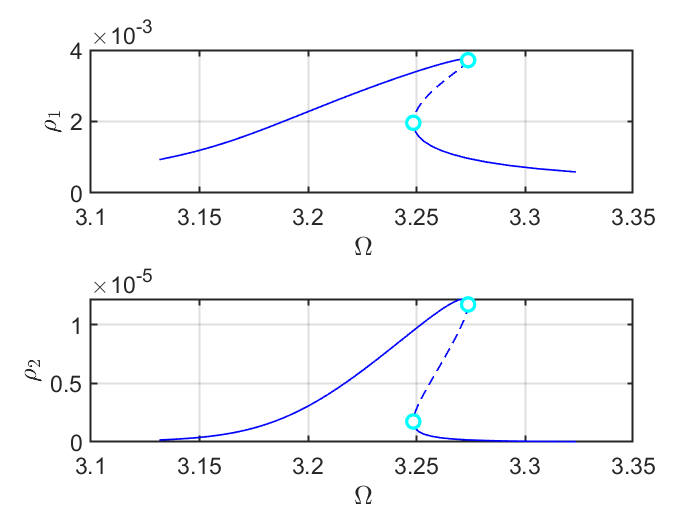

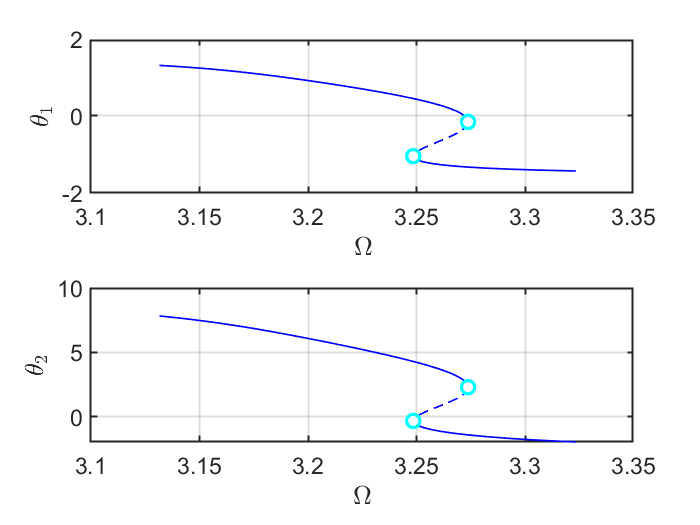

the forcing frequency 3.1315e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1329e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1406e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1476e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1540e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1598e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1653e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1705e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1754e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1801e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequenc

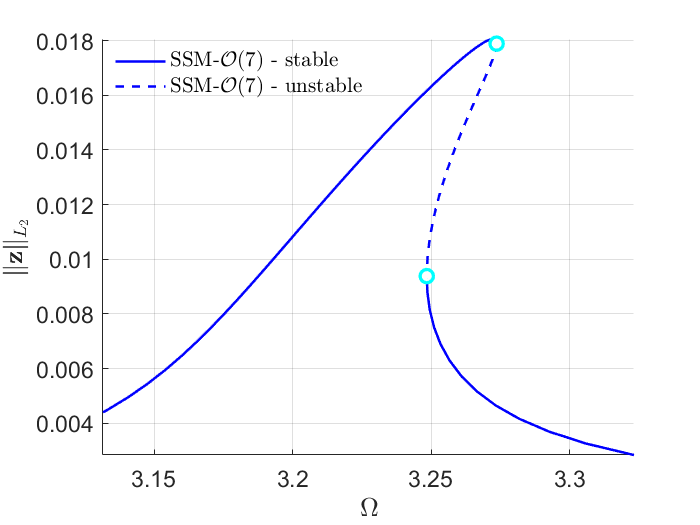

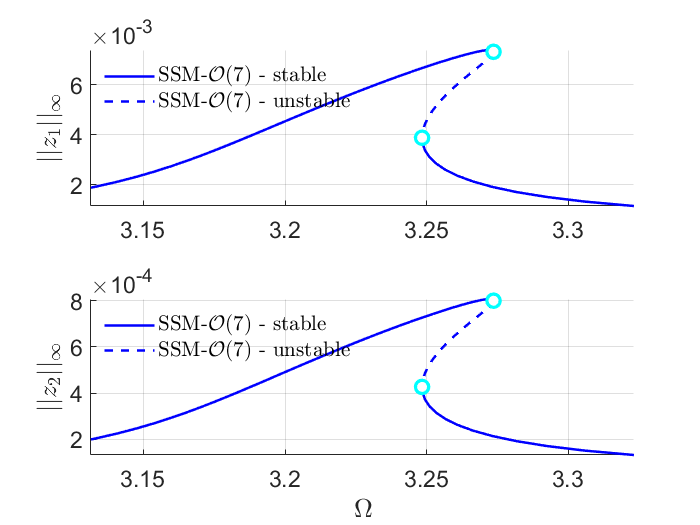

timings.FRC_ND_O5 = toc(start);
fig_ssm = gcf;
% O(7)
start = tic;
FRC_ND_O7 = S.SSM_isol2ep('isol-nd-7',resonant_modes, order+4, [1 3],...
    'freq', freqrange,outdof,{sol.p,sol.x});

timings.FRC_ND_O7 = toc(start);

Plot FRC at different orders in the same figure to observe the convergence 

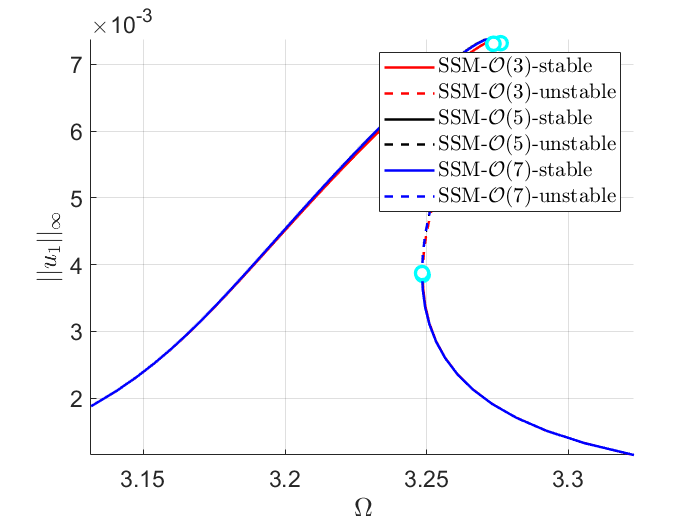

FRCs = {FRC_ND_O3,FRC_ND_O5,FRC_ND_O7};
thm = struct();
thm.SN = {'LineStyle', 'none', 'LineWidth', 2, ...
  'Color', 'cyan', 'Marker', 'o', 'MarkerSize', 8, 'MarkerEdgeColor', ...
  'cyan', 'MarkerFaceColor', 'white'};
thm.HB = {'LineStyle', 'none', 'LineWidth', 2, ...
  'Color', 'black', 'Marker', 's', 'MarkerSize', 8, 'MarkerEdgeColor', ...
  'black', 'MarkerFaceColor', 'white'};
color = {'r','k','b','m'};
figure(20);
ax1 = gca;
for k=1:3
    FRC = FRCs{k};
    SNidx = FRC.SNidx;
    HBidx = FRC.HBidx;
    FRC.st = double(FRC.st);
    FRC.st(HBidx) = nan;
    FRC.st(SNidx) = nan;
    % color
    ST = cell(2,1);
    ST{1} = {[color{k},'--'],'LineWidth',1.5}; % unstable
    ST{2} = {[color{k},'-'],'LineWidth',1.5};  % stable
    legs = ['SSM-$\mathcal{O}(',num2str(2*k+1),')$-unstable'];
    legu = ['SSM-$\mathcal{O}(',num2str(2*k+1),')$-stable'];
    hold(ax1,'on');
    plot_stab_lines(FRC.om,FRC.Aout_frc(:,1),FRC.st,ST,legs,legu);
    SNfig = plot(FRC.om(SNidx),FRC.Aout_frc(SNidx,1),thm.SN{:});
    set(get(get(SNfig,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off');
    HBfig = plot(FRC.om(HBidx),FRC.Aout_frc(HBidx,1),thm.HB{:});
    set(get(get(HBfig,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off');   
    xlabel('$\Omega$','Interpreter','latex'); 
    ylabel('$||u_1||_{\infty}$','Interpreter','latex'); 
    set(gca,'FontSize',14);
    grid on; axis tight; 
end

### Validation using collocation method from COCO

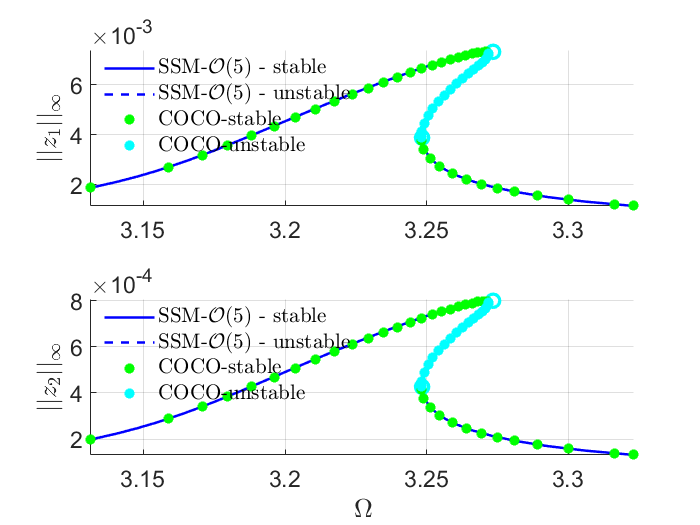


 Run='bd_nd.FRC': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          2.90e-04  5.26e+00    0.0    0.0    0.0
   1   1  1.00e+00  4.21e-02  2.64e-05  5.26e+00    0.0    0.2    0.0
   2   1  1.00e+00  3.17e-03  3.55e-07  5.26e+00    0.1    0.3    0.1
   3   1  1.00e+00  4.42e-05  6.25e-11  5.26e+00    0.1    0.5    0.1
   4   1  1.00e+00  7.80e-09  1.67e-17  5.26e+00    0.1    0.7    0.1

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps         amp1         amp2
    0  00:00:02   5.2599e+00      1  EP      3.1315e+00   2.0064e+00   1.5000e-04   1.8748e-03   1.9789e-04
   10  00:00:18   5.3338e+00      2          3.2294e+00   1.9456e+00   1.5000e-04   5.8545e-03   6.3780e-04
   20  00:00:30   5.3635e+00      3          3.2661e+00   1.9238e+00   1.5000e-04   7.2225e-03   7.8958e-04
   26  00:00:

figure(fig_ssm); hold on
nCycles = 500;
coco = cocoWrapper(DS, nCycles, outdof);
set(coco.Options, 'PtMX', 1000, 'NTST',20, 'dir_name', 'bd_nd');
set(coco.Options, 'NAdapt', 0, 'h_max', 200, 'MaxRes', 1);
coco.initialGuess = 'linear';
start = tic;
bd_nd = coco.extract_FRC(freqrange);

timings.cocoFRCbd_nd = toc(start)

timings = struct with fields:
       FRC_ND_O3: 12.9727
       FRC_ND_O5: 7.7826
       FRC_ND_O7: 10.3432
    cocoFRCbd_nd: 94.5069


## Linear Damping

### Setup Dynamical System

n = 10;
[mass,damp,gyro,stiff,fnl,fext] = build_model(n,'linear_damp');

the first four eigenvalues for undamped system


lamd =    0.0000 + 3.1954i
   0.0000 - 3.1954i
   0.0000 + 9.5862i
   0.0000 - 9.5862i



% Create model
DS = DynamicalSystem();
set(DS,'M',mass,'C',damp+gyro,'K',stiff,'fnl',fnl);
set(DS.Options,'Emax',6,'Nmax',10,'notation','multiindex');
set(DS.Options,'RayleighDamping',false,'BaseExcitation',true);
DS.add_forcing(coeffs, kappas, h);

### Linear Modal analysis

[V,D,W] = DS.linear_spectral_analysis();


 The first 6 eigenvalues are given as 
  -0.0180 + 3.1954i
  -0.0180 - 3.1954i
  -0.2721 + 9.5828i
  -0.2721 - 9.5828i
  -1.3571 +19.6071i
  -1.3571 -19.6071i



**Choose Master subspace **

S = SSM(DS);
set(S.Options, 'reltol', 1,'notation','multiindex');
resonant_modes = [1 2 3 4];
order = 5;
outdof = [1 2];

### Primary resonance of the first mode

(near) outer resonance detected for the following combination of master eigenvalues
     0     0     2     0
     1     0     2     0
     0     0     3     1
     1     1     2     0
     3     0     1     0
     0     2     3     0
     1     0     3     1
     2     1     2     0
     4     0     1     0
     0     0     4     2
     0     3     3     0
     1     1     3     1
     2     2     2     0
     3     0     2     1
     4     1     1     0
     6     0     0     0
     0     2     4     1
     1     0     4     2
     1     3     3     0
     2     1     3     1
     3     2     2     0
     4     0     2     1
     5     1     1     0
     7     0     0     0
     0     0     5     3
     0     3     4     1
     1     1     4     2
     1     4     3     0
     2     2     3     1
     3     0     3     2
     3     3     2     0
     4     1     2     1
     5     2     1     0
     6     0     1     1
     7     1     0     0
     0     2     5     2
     0     5    

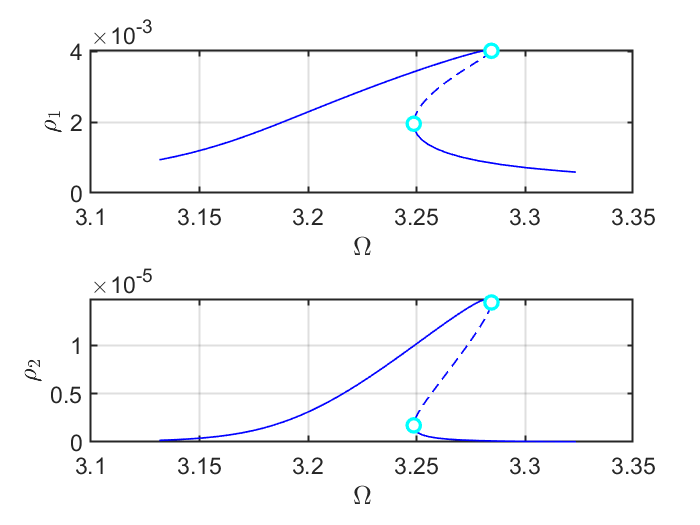

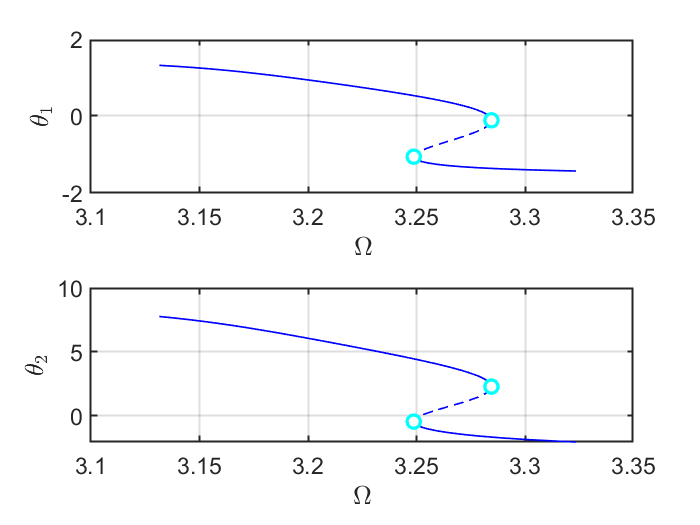

the forcing frequency 3.1315e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1386e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1458e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1524e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1585e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1641e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1695e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1745e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1794e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequency 3.1842e+00 is nearly resonant with the eigenvalue -1.7969e-02 + i3.1954e+00
the forcing frequenc

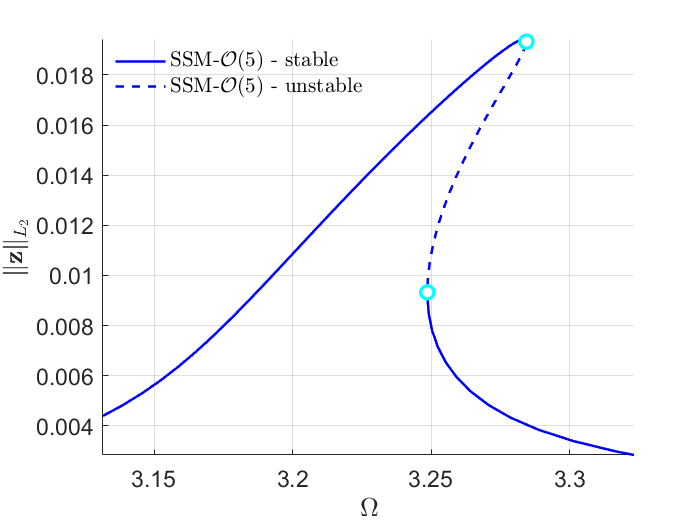

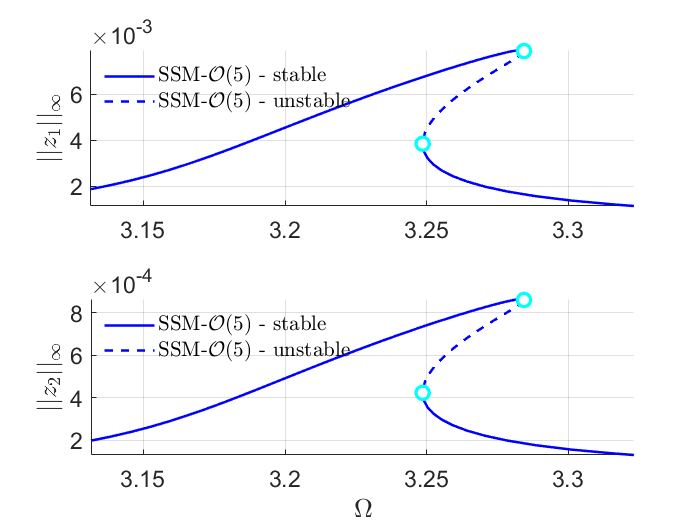

freqrange = [0.98 1.04]*imag(D(1));
set(S.FRCOptions, 'nCycle',500, 'initialSolver', 'fsolve');
set(S.contOptions, 'PtMX', 300, 'h0', 0.1, 'h_max', 0.2, 'h_min', 1e-3);
set(S.FRCOptions, 'coordinates', 'polar');

sol = ep_read_solution('isol-nd-3.ep',1);
start = tic;
FRC_LD_O5 = S.SSM_isol2ep('isol-ld-5',resonant_modes, order, [1 3],...
    'freq', freqrange,outdof,{sol.p,sol.x});

timings.FRC_LD_O5 = toc(start);

### validation using collocation method from COCO


 Run='bd_ld.FRC': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          2.90e-04  5.26e+00    0.0    0.0    0.0
   1   1  1.00e+00  4.21e-02  2.64e-05  5.26e+00    0.0    0.1    0.0
   2   1  1.00e+00  3.17e-03  3.55e-07  5.26e+00    0.0    0.2    0.0
   3   1  1.00e+00  4.42e-05  6.19e-11  5.26e+00    0.0    0.2    0.1
   4   1  1.00e+00  7.74e-09  1.86e-17  5.26e+00    0.0    0.3    0.1

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps         amp1         amp2
    0  00:00:01   5.2599e+00      1  EP      3.1315e+00   2.0064e+00   1.5000e-04   1.8752e-03   1.9793e-04
   10  00:00:11   5.3386e+00      2          3.2354e+00   1.9420e+00   1.5000e-04   6.1597e-03   6.7089e-04
   20  00:00:19   5.3722e+00      3          3.2764e+00   1.9177e+00   1.5000e-04   7.7132e-03   8.4203e-04
   26  00:00:

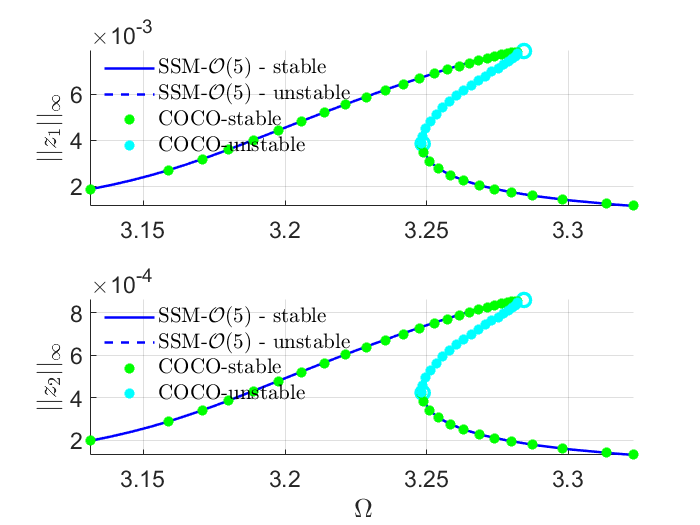

nCycles = 500;
coco = cocoWrapper(DS, nCycles, outdof);
set(coco.Options, 'PtMX', 1000, 'NTST',20, 'dir_name', 'bd_ld');
set(coco.Options, 'NAdapt', 0, 'h_max', 200, 'MaxRes', 1);
coco.initialGuess = 'linear';
start = tic;
bd_ld = coco.extract_FRC(freqrange);

timings.cocoFRCbd_ld = toc(start)

timings = struct with fields:
       FRC_ND_O3: 12.9727
       FRC_ND_O5: 7.7826
       FRC_ND_O7: 10.3432
    cocoFRCbd_nd: 94.5069
       FRC_LD_O5: 7.5735
    cocoFRCbd_ld: 67.0952


## Comparison of FRC with/without nonlinear damping

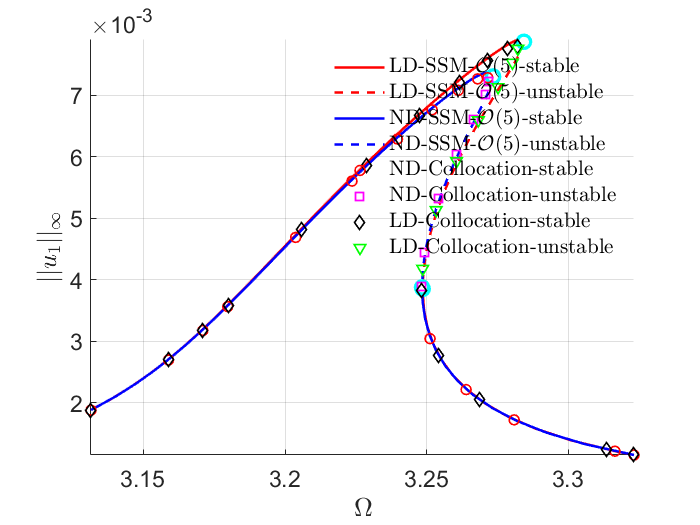

% plot SSM results
FRCs = {FRC_LD_O5,FRC_ND_O5};
legs = {'LD-SSM-$\mathcal{O}(5)$-unstable','ND-SSM-$\mathcal{O}(5)$-unstable'};
legu = {'LD-SSM-$\mathcal{O}(5)$-stable','ND-SSM-$\mathcal{O}(5)$-stable'};
color = {'r','b'};
fig25 = figure;
fig26 = figure;
for k=1:2
    FRC = FRCs{k};
    SNidx = FRC.SNidx;
    HBidx = FRC.HBidx;
    FRC.st = double(FRC.st);
    FRC.st(HBidx) = nan;
    FRC.st(SNidx) = nan;
    % color
    ST = cell(2,1);
    ST{1} = {[color{k},'--'],'LineWidth',1.5}; % unstable
    ST{2} = {[color{k},'-'],'LineWidth',1.5};  % stable
    figure(fig25); hold on
    plot_stab_lines(FRC.om,FRC.Aout_frc(:,1),FRC.st,ST,legs{k},legu{k});
    SNfig = plot(FRC.om(SNidx),FRC.Aout_frc(SNidx,1),thm.SN{:});
    set(get(get(SNfig,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off');  
    xlabel('$\Omega$','Interpreter','latex'); 
    ylabel('$||u_1||_{\infty}$','Interpreter','latex'); 
    set(gca,'FontSize',14);
    grid on, axis tight; 
    legend boxoff;
    figure(fig26); hold on
    plot_stab_lines(FRC.om,FRC.Aout_frc(:,2),FRC.st,ST,legs{k},legu{k});
    SNfig = plot(FRC.om(SNidx),FRC.Aout_frc(SNidx,2),thm.SN{:});
    set(get(get(SNfig,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off'); 
    xlabel('$\Omega$','Interpreter','latex'); 
    ylabel('$||u_2||_{\infty}$','Interpreter','latex'); 
    set(gca,'FontSize',14);
    grid on; axis tight; 
    legend boxoff
end

% load coco solution
legs = {'LD-Collocation-unstable','ND-Collocation-unstable'};
legu = {'LD-Collocation-stable','ND-Collocation-stable'};

bd = bd_nd{:};
ndom   = coco_bd_col(bd,'omega'); 
ndamp1 = coco_bd_col(bd, 'amp1');
ndamp2 = coco_bd_col(bd, 'amp2');
ndst   = coco_bd_col(bd, 'eigs');
ndst = all(abs(ndst)<1,1);
logs  = [1 2 3 4:3:numel(ndst)-4 numel(ndst)-1 numel(ndst)];
ndamp1 = ndamp1(logs);
ndamp2 = ndamp2(logs);
ndom = ndom(logs);
ndst = ndst(logs);
figure(fig25); hold on
plot(ndom(ndst), ndamp1(ndst), 'ro', 'MarkerSize', 6, 'LineWidth', 1,...
    'DisplayName', 'ND-Collocation-stable'); 
plot(ndom(~ndst), ndamp1(~ndst), 'ms', 'MarkerSize', 6, 'LineWidth', 1,...
    'DisplayName', 'ND-Collocation-unstable');
figure(fig26); hold on
plot(ndom(ndst), ndamp2(ndst), 'ro', 'MarkerSize', 6, 'LineWidth', 1,...
    'DisplayName', 'ND-Collocation-stable'); 
plot(ndom(~ndst), ndamp2(~ndst), 'ms', 'MarkerSize', 6, 'LineWidth', 1,...
    'DisplayName', 'ND-Collocation-unstable');

bd = bd_ld{:};
ldom   = coco_bd_col(bd,'omega'); 
ldamp1 = coco_bd_col(bd, 'amp1');
ldamp2 = coco_bd_col(bd, 'amp2');
ldst   = coco_bd_col(bd, 'eigs');
ldst = all(abs(ldst)<1,1);
logs  = [1 2 3 4:3:numel(ldst)-4 numel(ldst)-1 numel(ldst)];
ldamp1 = ldamp1(logs);
ldamp2 = ldamp2(logs);
ldom = ldom(logs);
ldst = ldst(logs);
figure(fig25); hold on
plot(ldom(ldst), ldamp1(ldst), 'kd', 'MarkerSize', 6, 'LineWidth', 1,...
    'DisplayName', 'LD-Collocation-stable'); 
plot(ldom(~ldst), ldamp1(~ldst), 'gv', 'MarkerSize', 6, 'LineWidth', 1,...
    'DisplayName', 'LD-Collocation-unstable');

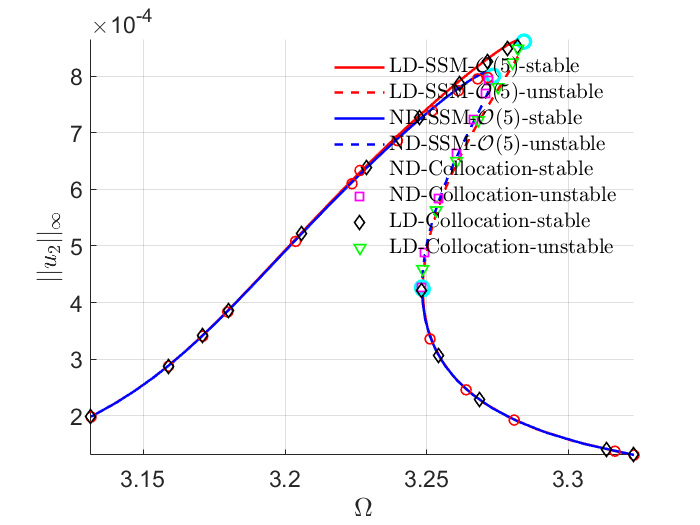

figure(fig26); hold on
plot(ldom(ldst), ldamp2(ldst), 'kd', 'MarkerSize', 6, 'LineWidth', 1,...
    'DisplayName', 'LD-Collocation-stable'); 
plot(ldom(~ldst), ldamp2(~ldst), 'gv', 'MarkerSize', 6, 'LineWidth', 1,...
    'DisplayName', 'LD-Collocation-unstable');

timings

timings = struct with fields:
       FRC_ND_O3: 12.9727
       FRC_ND_O5: 7.7826
       FRC_ND_O7: 10.3432
    cocoFRCbd_nd: 94.5069
       FRC_LD_O5: 7.5735
    cocoFRCbd_ld: 67.0952
